# Aula 7 - Compensador Avanço-Atraso

Projetar um compensador de Avanço-Atraso para $K_v=10$; $\zeta=0.6$ e $t_s^{2\%}<2.0s$.

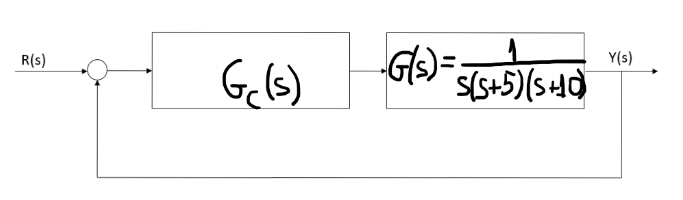

1º) Encontrar o pólo desejado:


$$t_s^{2\%}=\frac{4}{\zeta\omega_n}<2$$


clear;
close all
z=0.6;
ts=2;
w=4/ts/z

w = 3.3333

$\omega_n>3.3333$ rad/s

fazendo $\omega_n=3.4$ rad/s temos:

wn=3.4;
s=-z*w+j*w*sqrt(1-z^2)

s = -2.0000 + 2.6667i


$$s^{desejado}=-\zeta\omega_n\pm j\omega_n\sqrt{1-\zeta^2}=-2\pm2.67j$$


2º) Verificar o avanço nessessário.

den=conv(conv([1,0],[1,5]),[1,10]);
G=tf(1,den)

G =
 
           1
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.



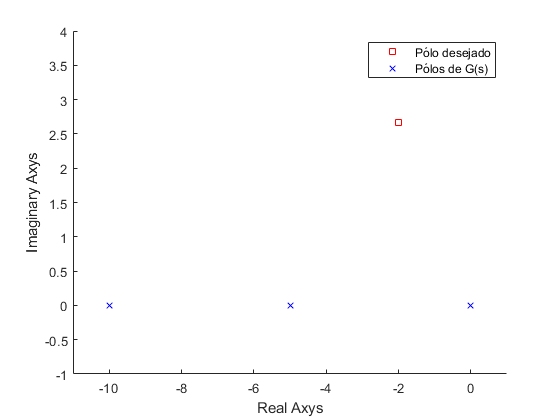

p=pole(G);
scatter(real(s),imag(s),'s',"MarkerEdgeColor",'Red')
hold on
for n=1:length(p)
    scatter(p(n),0,'x',"MarkerEdgeColor",'Blue')
end
axis([-11,1,-1,4])
legend('Pólo desejado','Pólos de G(s)')
xlabel('Real Axys')
ylabel('Imaginary Axys')
hold off

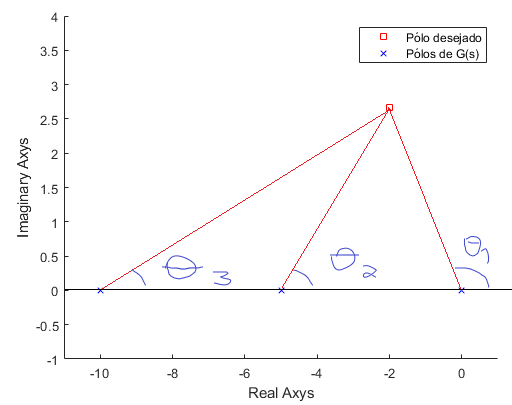

Condição de Fase:

$\sum_m \phi_i - \sum_n \theta_j =180º \pm k360º$ , para $k$ inteiro

theta1=180-atand(imag(s)/(p(1)-real(s)))

theta1 = 126.8699

theta2=atand(imag(s)/(real(s)-p(2)))

theta2 = 18.4349

theta3=atand(imag(s)/(real(s)-p(3)))

theta3 = 41.6335

avanco=-180+theta1+theta2+theta3

avanco = 6.9384

3º) Chutar uma posição para o zero do compensador de avanço:

Fórmula geral do compensador de avanço: $G_{av}=K_{av}\frac{1+sT}{1+s\alpha T}$.

Adiciona um zero e um pólo e o zero deve ficar a direita do pólo($\alpha<1$). 

Colocando um zero em $s=-2$ temos:

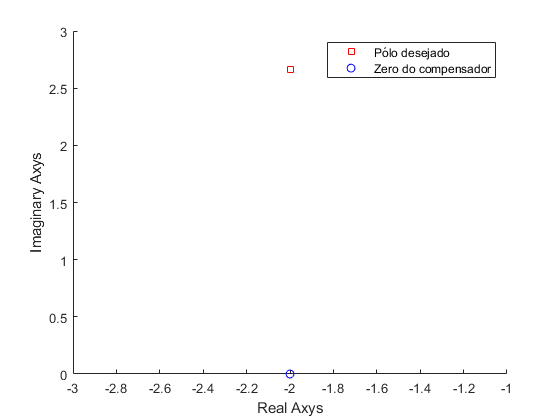

z=-2;
T=-1/z;
scatter(real(s),imag(s),'s',"MarkerEdgeColor",'Red');
hold on
scatter(z,0,'o',"MarkerEdgeColor",'Blue')
legend("Pólo desejado","Zero do compensador")
xlabel('Real Axys')
ylabel('Imaginary Axys')
hold off

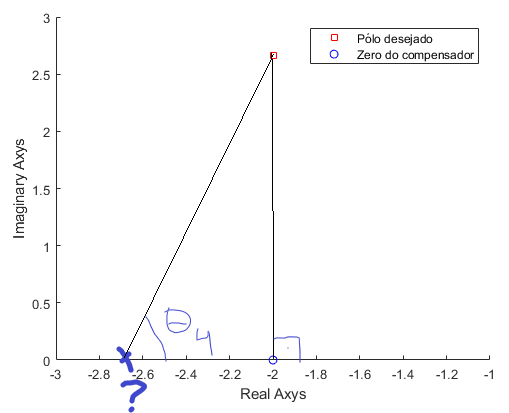

theta4=90-avanco

theta4 = 83.0616

x=real(s)/tan(theta4);
pav=real(s)+x

pav = -2.3859

alpha=-1/(pav*T)

alpha = 0.8383

Se $T=0.5$ e $\alpha=0.8383$ temos $G_{av}=K_{av}\frac{1+0.5s}{1+0.419s}$

4º) Encontrar $K_{av}$ pela Condição de Módulo:


$$\left| G_{av} G \right|_{s=s_{desejado}} =1$$


Gs=1/(s*(s+5)*(s+10));
Gavs=(1+T*s)/(1+alpha*T*s);
Kav=1/abs(Gs)/abs(Gavs)

Kav = 95.5639

Gav=Kav*tf([T,1],[T*alpha,1])

Gav =
 
  47.78 s + 95.56
  ---------------
   0.4191 s + 1
 
Continuous-time transfer function.




$$G_{av}=\frac{47.78s+95.96}{0.4191s+1}$$


5º) Encontrar $K_{at}$ para $K_v=10$:

Fórmula geral do compensador de atraso: $G_{at}=K_{at}\frac{1+sT}{1+s\beta T}$.

Adiciona um zero e um pólo e o zero deve ficar a esquerda do pólo($\beta>1$). Como o objetivo do controlador de atraso é não alterar muito o lugar das raízes do sistema, o pólo e o zero adicionados devem estar próximos o suficiente para $|\theta-\phi|\leq5º$. Além disso, $\frac{K_{at}}{\beta}=1$.


$$K_v=\lim_{s\rightarrow0}sG_{at}G_{av}G=\lim_{s\rightarrow0}sK_{at}\frac{1+sT}{1+s\beta T}\frac{47.78s+95.96}{0.4191s+1}\frac{1}{s(s+5)(s+10)}$$


Como no compensador de atraso o pólo e o zero são muito próximos,


$$K_v=K_{at}\frac{98.96}{5\times10}=10$$


Kat=10*10*5/98.96

Kat = 5.0525


$$K_{at}=\beta=5.0525$$


6º) Chutar valor de T e verificar se $|\theta-\phi|\leq5º$ e se atende os requsitos de projeto:

Fazendo $T=100$

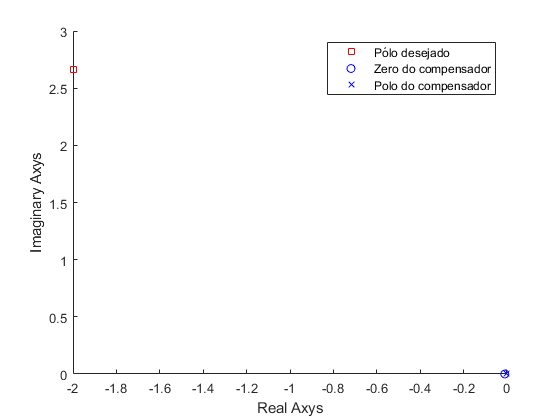

T=100;
beta=Kat;
pat=-1/(beta*T); %pólo do compensador de atraso
zat=-1/T; %zero do compensador de atraso
scatter(real(s),imag(s),'s',"MarkerEdgeColor",'Red');
hold on
scatter(zat,0,'o',"MarkerEdgeColor",'Blue')
scatter(pat,0,'x',"MarkerEdgeColor",'Blue')
legend("Pólo desejado","Zero do compensador","Polo do compensador")
xlabel('Real Axys')
ylabel('Imaginary Axys')
hold off

theta=180-atand(imag(s)/(pat-real(s)))

theta = 126.8427

phi=180-atand(imag(s)/(zat-real(s)))

phi = 126.7321

LogicalStr = {'Não, escolhe outro valor de T.', 'Sim, valor de T aceito.'};
fprintf(' Módulo de (Phi - Theta) é menor que 5 graus? \n %s',LogicalStr{(abs(theta-phi)<5)+1})

 Módulo de (Phi - Theta) é menor que 5 graus? 
 Sim, valor de T aceito.

Gat=Kat*tf([T,1],[T*beta,1])

Gat =
 
  505.3 s + 5.053
  ---------------
    505.3 s + 1
 
Continuous-time transfer function.



$G_{at}=\frac{505.3s+5.053}{505.3s+1}$.

sys=feedback(Gat*Gav*G,1);
stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.6531
    SettlingTime: 1.7829
     SettlingMin: 0.9183
     SettlingMax: 1.0488
       Overshoot: 4.8779
      Undershoot: 0
            Peak: 1.0488
        PeakTime: 1.3581


damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e-02                 1.00e+00       1.00e-02         9.96e+01    
 -1.73e+00                 1.00e+00       1.73e+00         5.78e-01    
 -2.04e+00 + 2.68e+00i     6.06e-01       3.37e+00         4.90e-01    
 -2.04e+00 - 2.68e+00i     6.06e-01       3.37e+00         4.90e-01    
 -1.16e+01                 1.00e+00       1.16e+01         8.65e-02    


y=step(sys);
ess=1-y(end);
Kv=1/ess

Kv = 174.7122